clear
clc
close all

%% Change directory
% Get the full path of the currently running script
if isdeployed
    % If the code is deployed, use the built-in method
    scriptFullPath = mfilename('fullpath');
else
    % If running in the MATLAB environment, use the editor API
    scriptFullPath = matlab.desktop.editor.getActiveFilename;
end

% Extract the directory part of the path
[scriptDir, ~, ~] = fileparts(scriptFullPath);

% Change the current directory to the script's directory
cd(scriptDir);

% Display the current directory to confirm the change
disp(['Current directory changed to: ', scriptDir]);

Current directory changed to: C:\Users\giaco\Git_Repositories\Semester_Thesis_1


data25 = readtable('data/temperature25.xlsx');
data50 = readtable('data/temperature50.xlsx');
data75 = readtable('data/temperature75.xlsx');

data = vertcat(data25, data50, data75);

data25_sorted = sortrows(data25, 'Current_A');
data50_sorted = sortrows(data50, 'Current_A');
data75_sorted = sortrows(data75, 'Current_A');

## Regressions

Linear

%x1 = current
%x2 = delta T
%x3 = T hot side
X = [data.Current_A, data.DeltaT_C, data.Th_C];

y1 = data.Qremoved_W;
mdl_Q_removed = fitlm(X, y1, 'y ~ x1*x2*x3 + x1^2 + x2^2 - x1:x2:x3');

y2 = data.Qwaste_W;
mdl_Q_waste = fitlm(X, y2, 'y ~ x1*x2*x3 - x1:x2:x3');

y3 = data.Voltage_V;
mdl_voltage = fitlm(X, y3, 'y ~ x1*x2*x3 - x2:x3 - x1:x2:x3');

Nonlinear

y4 = data.COP;

modelFun = @(b, X) ((b(1)*X(:,1).^3 + b(2)*X(:,1).^2 + b(3)*X(:,1) + b(4)) ./ ...
                   (b(5)*X(:,1).^3 + b(6)*X(:,1).^2 + b(7)*X(:,1) + b(8))) + ...
                   (b(9)*X(:,2).^2 + b(10)*X(:,2) + b(11)) + ...
                   (b(12)*X(:,3));

initialGuess = [-70, 900, 1500, -490, 145, 292, 61, 0, 1, 1, 1, 1];

mdl_COP = fitnlm(X, y4, modelFun, initialGuess)

mdl_COP = Nonlinear regression model:
    y ~ F(b,X)

Estimated Coefficients:
            Estimate        SE         tStat        pValue 
           __________    ________    __________    ________

    b1        -5857.2     0.24864        -23557           0
    b2     1.9009e+05      1.0533    1.8048e+05           0
    b3         -43316      4.5045         -9616           0
    b4         43.088      20.348        2.1176    0.034345
    b5         -26382      20.353       -1296.2           0
    b6         5995.9      85.523        70.109           0
    b7         54.529      364.94       0.14942     0.88124
    b8     -0.0043518    0.035883      -0.12128     0.90348
    b9        0.07767     0.0841

## Plot

curr    = linspace(1,6,6);      %A
deltaT  = linspace(0,60,7);     %°C
T_hot   = linspace(25,75,3);    %°C

curr_str    = string(curr);
deltaT_str  = string(deltaT);
T_hot_str   = string(T_hot);

curr_len    = length(curr_str);
deltaT_len  = length(deltaT_str);
T_hot_len   = length(T_hot_str);

curr_colormap   = winter(curr_len);
deltaT_colormap = autumn(deltaT_len);
T_hot_colormap  = autumn(T_hot_len);

% Dictionary for the labels
headers_keys = data.Properties.VariableNames;
label_values = ["Hot side temperature / °C", ...
                "Input voltage / V", ...
                "Temperature difference / °C", ...
                "Current / A", ...
                "Heat from cold side / W", ...
                "Heat to hot side / W", ...
                "Coefficient of performance COP / -"];
label_dict = containers.Map(headers_keys, label_values);

% Dictionary for the legends
headers_keys = data.Properties.VariableNames;
legend_values = ["T_h = ", ...
                 "U = ", ...
                 "\Delta T = ", ...
                 "I = ", ...
                 "Q_{in} = ", ...
                 "Q_{out}", ...
                 "COP = "];
legend_dict = containers.Map(headers_keys, legend_values);

% Dictionary for the units
headers_keys = data.Properties.VariableNames;
units_values = ["°C", ...
                "V", ...
                "°C", ...
                "A", ...
                "W", ...
                "W", ...
                ""];
units_dict = containers.Map(headers_keys, units_values);

#### Voltage vs DeltaT 4every Current

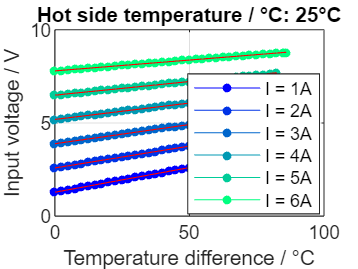

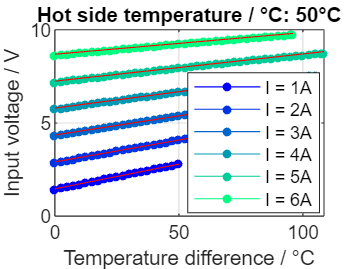

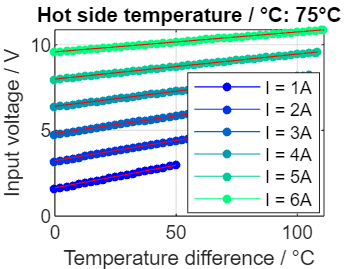

for j = 1:T_hot_len
    figure
    hold on
    
    for i = 1:curr_len
        mask = data.Current_A == curr(i) & data.Th_C == T_hot(j);
        x2plot = data.DeltaT_C(mask);
        y2plot = data.Voltage_V(mask);
    
        p = plot(x2plot, y2plot);
        p.DisplayName = legend_dict(headers_keys{4}) + curr_str(i) + units_dict(headers_keys{4});
        p.LineStyle = '-';
        p.Marker = '.';
        p.Color = curr_colormap(i,:);
        p.MarkerSize = 12;
    
        xpred = [repmat(curr(i), length(x2plot), 1), ...            %x1 = current
                 x2plot, ...                                        %x2 = delta T
                 repmat(T_hot(j), length(x2plot), 1)];              %x3 = T hot side
        ypred = predict(mdl_voltage, xpred);
    
        p_pred = plot(x2plot, ypred);
        p_pred.HandleVisibility = 'off';
        p_pred.LineStyle = '-';
        p_pred.Color = 'r';
    end
    
    xlabel(label_dict(headers_keys{3}));
    ylabel(label_dict(headers_keys{2}));
    lg = legend('Location','best');
    lg.FontSize = 8;
    title(label_dict(headers_keys{1}) + ": "+ T_hot_str(j) + units_dict(headers_keys{1}));
    grid on
    box on
    
    hold off
end